# MXB201 Exercises 1

## Theory

### Prove, or provide a counterexample

T1.  It is not possible for a linear system of equations $Ax = b$ to have exactly two solutions.

A system can only be consistent with either one or infinitely many solutions. This is because solutions lie on the intersection of vectors on two or more subspaces, hence we can either have a point, a line, a plane, etc. of possible solutions.

T2.  If a square linear system $Ax = b$ has at least one solution, then $\textrm{nullity}(A) = 0$.

If at least one solution exists, we can expect infinitely many to exist also. This means we can have a matrix A with a row of zeros or has free variables, indicating that the nullity is not always 0.

T3.  The column space of the RREF of a matrix $A$ is the same as the column space of $A$.

T4.  If two square matrices have the same row space as each other, then they have the same column space as each other.

T5.  If a vector $v$ is orthogonal to all vectors in a basis for some space $W$, then $v$ is orthogonal to every vector in $W$.

T6.  If all vectors in a basis for some space $V$ are orthogonal to all vectors in a basis for some space $W$, then every vector in $V$ is orthogonal to every vector in $W$.

## Practice

P1.  Find bases for the row space, column space and null space of the following matrices.  If you want/need the practice with row operations, start from the matrix $A$ and derive the RREF.  Otherwise, use the provided RREF $R$.  Do the rest of the working yourself.  You can check your answers at the end using MATLAB's `colspace` and `null` commands.

A_i = sym([3 1 -3 ; 3 2 0 ; 2 1 -1]), R_i = rref(A_i)

$$A\_i = \left(\begin{array}{ccc} 3 & 1 & -3\\ 3 & 2 & 0\\ 2 & 1 & -1 \end{array}\right)$$

$$R\_i = \left(\begin{array}{ccc} 1 & 0 & -2\\ 0 & 1 & 3\\ 0 & 0 & 0 \end{array}\right)$$

row_i = sym([1 0; 0 1; -2 3])

$$row\_i = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -2 & 3 \end{array}\right)$$

null_i = sym([2; -3; 1])

$$null\_i = \left(\begin{array}{c} 2\\ -3\\ 1 \end{array}\right)$$

A_ii = sym([0 2 2 -3 ; 0 1 2 -3 ; 0 3 2 -3]), R_ii = rref(A_ii)

$$A\_ii = \left(\begin{array}{cccc} 0 & 2 & 2 & -3\\ 0 & 1 & 2 & -3\\ 0 & 3 & 2 & -3 \end{array}\right)$$

$$R\_ii = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -\frac{3}{2}\\ 0 & 0 & 0 & 0 \end{array}\right)$$

row_ii = sym([0 0; 1 0; 0 1; 0 -3/2])

$$row\_ii = \left(\begin{array}{cc} 0 & 0\\ 1 & 0\\ 0 & 1\\ 0 & -\frac{3}{2} \end{array}\right)$$

null_ii = sym([1 0; 0 0; 0 3/2; 0 1])

$$null\_ii = \left(\begin{array}{cc} 1 & 0\\ 0 & 0\\ 0 & \frac{3}{2}\\ 0 & 1 \end{array}\right)$$

A_iii = sym([-7 1 -6 -2 ; 0 -1 -1 3 ; 1 0 1 -1 ; 1 -1 0 2 ; 3 -2 1 0]), R_iii = rref(A_iii)

$$A\_iii = \left(\begin{array}{cccc} -7 & 1 & -6 & -2\\ 0 & -1 & -1 & 3\\ 1 & 0 & 1 & -1\\ 1 & -1 & 0 & 2\\ 3 & -2 & 1 & 0 \end{array}\right)$$

$$R\_iii = \left(\begin{array}{cccc} 1 & 0 & 1 & 0\\ 0 & 1 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

row_iii = sym([1 0 0; 0 1 0; 1 1 0; 0 0 1])

$$row\_iii = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 1 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

null_iii = sym([-1; -1; 1; 0])

$$null\_iii = \left(\begin{array}{c} -1\\ -1\\ 1\\ 0 \end{array}\right)$$

P2.  Find the general solutions to the linear systems $Ax = b$ for matrices $A$ of question P1, with the following right hand sides $b$.

b_i = sym([-4;7;1]), Rz_i = rref([A_i b_i])

$$b\_i = \left(\begin{array}{c} -4\\ 7\\ 1 \end{array}\right)$$

$$Rz\_i = \left(\begin{array}{cccc} 1 & 0 & -2 & -5\\ 0 & 1 & 3 & 11\\ 0 & 0 & 0 & 0 \end{array}\right)$$

b_ii = sym([2;4;0]), Rz_ii = rref([A_ii b_ii])

$$b\_ii = \left(\begin{array}{c} 2\\ 4\\ 0 \end{array}\right)$$

$$Rz\_ii = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & -2\\ 0 & 0 & 1 & -\frac{3}{2} & 3\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

b_iii = sym([-7;9;-2;7;6]), Rz_iii = rref([A_iii b_iii])

$$b\_iii = \left(\begin{array}{c} -7\\ 9\\ -2\\ 7\\ 6 \end{array}\right)$$

$$Rz\_iii = \left(\begin{array}{ccccc} 1 & 0 & 1 & 0 & 0\\ 0 & 1 & 1 & 0 & -3\\ 0 & 0 & 0 & 1 & 2\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

P3. Anton's Exercise Set 4.7

Questions 1,3,5,7,9,11,15,17, and the true-false exercises.

P4. Anton's Exercise Set 4.8

Questions 1,3,5,7,9,15,17,19,21,27, and the true-false exercises.

## Application

### A1. Production Cost Model

Suppose you work for a health food company which wishes to produce 1000 kilograms of a new vitamin tablet, containing 0.25% folic acid, 0.25% vitamin B-6, 12% calcium, and 2% iron.  The tablets are to be made from a mixture of six preparations (labelled $A$ through to $F$) that can be obtained from your company's distributor.  The relevant vitamin content of these six preparations is given in the following table.


$$\matrix{ \ &  \textrm{\% Folic Acid} & \textrm{\% Vitamin B-6} & \textrm{\% Calcium} & \textrm{\% Iron} & \textrm{Cost (\$ / kg)} \cr
A & 0.1 & 0.1 & 18 & 3 & 4.2 \cr
B & 0.3 & 0.0 & 9 & 3 & 3.7 \cr
C & 0.2 & 0.4 & 14 & 1 & 2.5 \cr
D & 0.1 & 0.5 & 19 & 1.2 & 5.6 \cr
E & 0.4 & 0.2 & 10 & 2 & 7.2 \cr
F & 0.2 & 0.2 & 11 & 3 & 4.5}$$


(i) Write a system of equations whose solution will provide the appropriate amount of each preparation.

(ii) Analyse and solve this system of equations.  How many solutions are possible?

(iii) Express the cost in terms of a single variable.

(iv) What value of the variable used in (iii) gives the minimum cost?

(v) How much of each ingredient should be used to obtain the product at minimum cost?

### A2. Balancing Chemical Equations

*For more background, read Anton's section on Balancing Chemical Equations, Section 1.9, pages 88--91.*

To balance the chemical equation


$$x_1\, CH_4 + x_2\, O_2 \to x_3\, CO_2 + x_4\, H_2O$$


we need to determine integer coefficients $x_i$ such that the number of atoms of each element (C, H, O) are equal on the left and right hand sides of the equation.

For Carbon (C), we require


$$x_1 = x_3$$


For Hydrogen (H), we require


$$4x_1 = 2x_4$$


For Oxygen (O), we require


$$2x_2 = 2x_3 + x_4$$


This is really a homogeneous linear system of equations in disguise.  Take all the unknowns to the left hand side, and we have


$$x_1 - x_3 = 0$$



$$4x_1 - 2x_4 = 0$$



$$2x_2 - 2x_3 - x_4 = 0$$


which is a homogeneous system of 3 equations in 4 unknowns.

The general solution then, is determined by finding the nullspace of the coefficient matrix.

A = sym([1 0 -1 0 ; 4 0 0 -2 ; 0 2 -2 -1])

$$A = \left(\begin{array}{cccc} 1 & 0 & -1 & 0\\ 4 & 0 & 0 & -2\\ 0 & 2 & -2 & -1 \end{array}\right)$$

x = null(A)

$$x = \left(\begin{array}{c} \frac{1}{2}\\ 1\\ \frac{1}{2}\\ 1 \end{array}\right)$$

Mathematically, *any* scalar multiple of this nullspace vector is a valid solution.  Physically, we cannot have fractions of molecules, so the smallest legitimate solution is twice this vector.

x*2

$$ans = \left(\begin{array}{c} 1\\ 2\\ 1\\ 2 \end{array}\right)$$

So, the balanced equation reads:


$$CH_4 + 2 O_2 \to CO_2 + 2H_2O$$


Complete Anton's Example 5, and Exercise Set 1.9 questions 9-12 (p. 95).  Or else choose any other chemical equations you like (look up some online!) and balance those.

### A3. Geometry

Find the parametric representation of the line at which the two planes $x + 2y - 3z = 2$ and $2x - y + z = -2$ intersect.

Check your answer visually.  You can use MATLAB's `fimplicit3` to plot the planes, and `fplot3` to plot the line, all on the same figure.  Use, say, a thick red line to make it stand out.

As usual, check the MATLAB documentation for how to use any MATLAB functions you're not familiar with.

## Exploration

### E1. Minimum Norm Solution

Lots of things to make you think in this question!  Take it slowly, refer back to the notes often.  It takes time for things to sink in, but this is a good learning exercise.

In Section 1.4 of Chapter 1, we used calculus techniques to find the minimim norm solution to $Ax=b$ for a rectangular matrix with a nonempty nullspace.  Rerun that file from Section 1.4 onwards (you can click Run to End on the toolbar) to populate MATLAB with all the variables for that example.

- Show (in MATLAB) that the minimum norm solution we called `x_min_nrm` belongs to the row space of $A$.

- Show (in MATLAB) that the minimum norm solution we called `x_min_nrm` is orthogonal to the null space of $A$.

- Explain (on paper) why statements 1--2 are equivalent.

- Write down (on paper) an extended system of equations that enforces *both* that $Ax = b$ and that $x$ is orthogonal to the null space of $A$.

- Explain (on paper) why this extended system of equations is guaranteed to have a unique solution.

- Form and solve (in MATLAB) your extended system of equations to confirm you recover `x_min_nrm`.

- Explain (on paper) why it must be that the minimum norm solution satisfies 1--2.  Hint: the solution has the minimum norm possible!

Evidently, applying calculus to the problem of finding the minimum norm solution was overkill!  If we were smarter, we could have reasoned as above, and just picked the minimum norm solution we sought from the row space of $A$.  We'll revisit this idea in later chapters.  In fact, we'll see on numerous occasions how linear algebra provides elegant solutions to problems that might have appeared to require calculus in order to solve.

### E2. Trigonometric Polynomials

A trigonometric polynomial of degree $n$ is a function of the form


$$p_n(t) = \sum_{k=0}^n a_k \cos(kt) + \sum_{k=1}^n b_k \sin(kt)$$


Trigonometric polynomials are useful for approximating periodic functions, say by using interpolation.  For example, consider the function

$f(t) = \exp(\sin(t))$ on the interval $t \in [0, 2\pi]$.

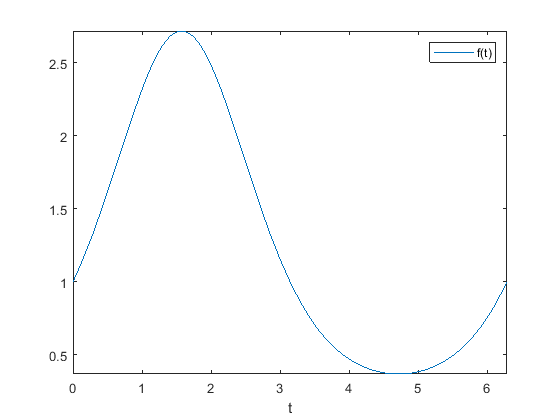

f = @(t) exp(sin(t));
figure, fplot(f, [0,2*pi], 'DisplayName','f(t)')
xlabel t; legend

One can approximate this function by a trigonometric polynomial of degree $n = 2$ (say), by sampling the function $f$ at the equally spaced values $t_0,\ldots, t_4  = 0,\ 2\pi/5,\ 4\pi/5,\ 6\pi/5,\ 8\pi/5$.

Then, imposing the interpolation conditions $p_2(t_k) = f(t_k)$ for $k = 0,\ldots, 4$ generates a linear system of equations for the unknown coefficients $a_k$ and $b_k$ in the interpolant$p_2(t) = a_0 + a_1 \cos(t) + a_2 \cos(2t) + b_1 \sin(t) + b_2 \sin(2t)$.

For example, we require $p_2(t_0) = f(t_0)$, so the first equation reads:


$$a_0 + a_1 \cos(t_0) + a_2 \cos(2t_0) + b_1 \sin(t_0) + b_2 \sin(2t_0) = \exp(\sin(t_0))$$


or more simply,

$a_0 + a_1 + a_2 = 1$.

With pen and paper, write out the full $5 \times 5$ system of equations obtained (this is just to confirm you have things clear in your mind).

Then, enter the coefficient matrix and right-hand-side vector in MATLAB.  Use whatever shortcuts you find convenient to cut down on the typing required.

Solve the linear system (using backslash is fine) to obtain the required coefficients for your trigonometric polynomial.

Plot this trigonometric polynomial on the same axes as the function.  You should find your solution looks like this.

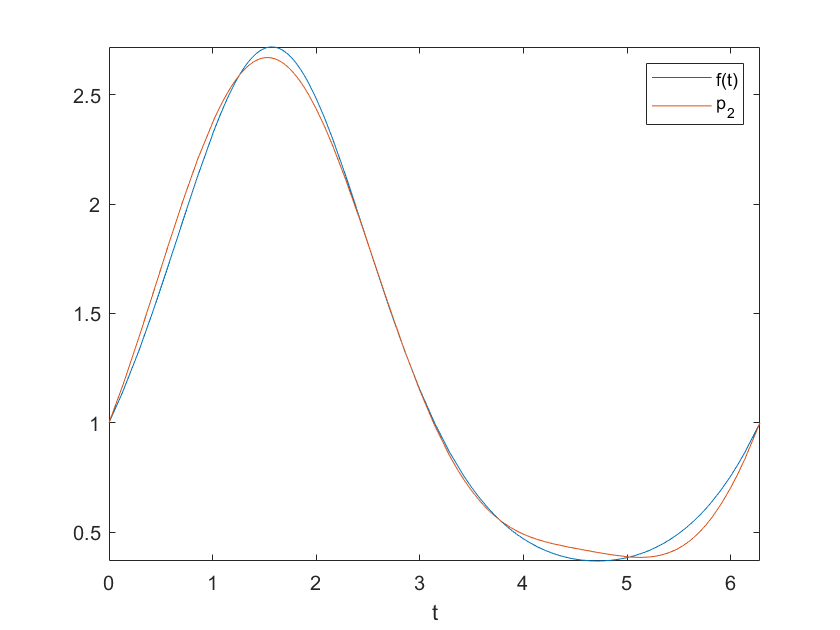

## Software

### S1. Linear Solver

Write a MATLAB function `linear_solve` that takes as input an $m\times n$ symbolic matrix $A$ and $n \times 1$ right hand side vector $b$, and returns the solution $x$ to $Ax = b$.  It should:

- output an error message if there is no solution

- output a warning message if there are infinitely many solutions

- return the general solution (not just a particular solution) if there are infinitely many solutions

- not use MATLAB's backslash command

- use the commands `rank`, `null`, `rref2`, or whatever else seems helpful.

Test your function out on various examples to check it handles all the different cases correctly.

### S2. Trigonometric Polynomials

Write a MATLAB program that computes the trigonometric polynomial interpolant for any $2\pi$-periodic function $f$ and any degree $n$.  Pick a few periodic functions, and have fun plotting their first few trigonometric interpolants.  How quickly do the interpolants converge to the true function?  Does it depend on how smooth the functions are?  Be sure to test out some definitely not smooth functions (like a square wave, for example).

### S3. Application Solvers

Write MATLAB programs to solve problems A1--A3 for general inputs.